fs = 500;
t_sample = 1/fs;
t = 0:t_sample:30;
omega = 29;
v = sin(omega*t);
f = omega/(2*pi)

f = 4.6155

T = 1/f

T = 0.2167

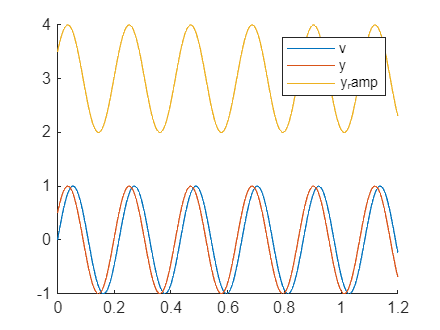

phase = pi/6;

y=  sin( (omega*t) + phase);

y_ramp = 1.0*y + 3.0 + t*0.0;
figure
hold on
plot(t,v)
plot(t,y)
plot(t,y_ramp)
hold off
legend(["v","y","y_ramp"])

xlim([0 1.2])

%% debias
t_start = 5;
idx_start = t_start/t_sample +1;
y_ramp_focus = y_ramp(idx_start:idx_start+max_samples_per_period);
t_focus = t(idx_start:idx_start+max_samples_per_period);
Integ = trapz(t_focus,y_ramp_focus)

Integ = 0.6551

b = Integ/T;


y_deb = y_ramp_focus - b;
trapz(t_focus,y_deb)

ans = -0.0040

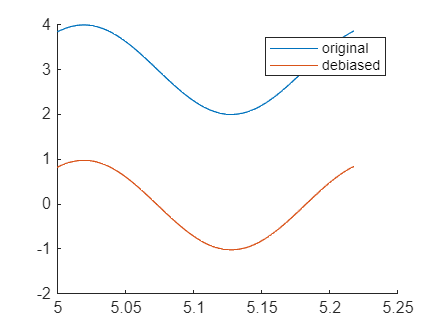

figure
hold on
plot(t_focus,y_ramp_focus)
plot(t_focus,y_deb)
legend(["original","debiased"])
hold off



max_samples_per_period = ceil(T/t_sample);
maxlag_n = ceil(max_samples_per_period/4) % just +-90° per side

maxlag_n = 28

[c,lags] = xcorr(v,y,maxlag_n,'none' );
c_ramp = xcorr(v,y_ramp,maxlag_n,'none' );

norm_factor = size(t,2)/2;
c = c/norm_factor;
c_ramp = c_ramp/norm_factor;

[c_max, cmaxid] = max(c)

c_max = 1.0001

cmaxid = 38

[c_ramp_max, cmax_ramp_id] = max(c_ramp)

c_ramp_max = 1.0129

cmax_ramp_id = 38



maxlag_time = (2*maxlag_n + 1) * t_sample

maxlag_time = 0.1140

lags_time = lags * t_sample

lags_time =    -0.0560   -0.0540   -0.0520   -0.0500   -0.0480   -0.0460   -0.0440   -0.0420   -0.0400   -0.0380   -0.0360   -0.0340   -0.0320   -0.0300   -0.0280   -0.0260   -0.0240   -0.0220   -0.0200   -0.0180   -0.0160   -0.0140   -0.0120   -0.0100   -0.0080   -0.0060   -0.0040   -0.0020         0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420


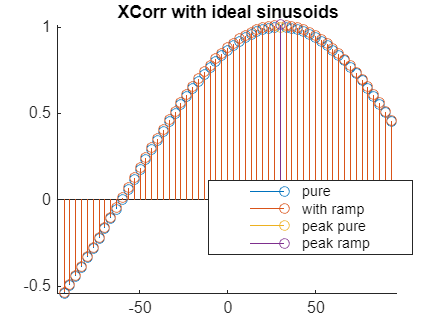

lags_angle = lags_time * 360 / T;




figure
hold on
stem(lags_angle,c)
stem(lags_angle,c_ramp)
stem(lags_angle(cmaxid),c_max)
stem(lags_angle(cmax_ramp_id),c_ramp_max)
title("XCorr with ideal sinusoids")
legend(["pure", "with ramp","peak pure","peak ramp"], "Position", [0.5543 0.2845 0.3035, 0.1142])
hold off;